# **Problems Week 5**

**Answer: **[**https://docs.google.com/document/d/14G1tAmEslRn6c8Ev_ghlicamyIzFlMe7XjAv1AP2p1s/edit**](https://docs.google.com/document/d/14G1tAmEslRn6c8Ev_ghlicamyIzFlMe7XjAv1AP2p1s/edit)

Plotting the function is a good idea to get an idea of where the roots are and provide initial guesses, then the methods can be used to get an accurate estimation. 

You can also substitute your answers back into the equation to see if it is correct (anonymous functions can help with that).

## **P5-1**

Use the roots function to find the roots of the polynomial.

## 
$$p\left(x\right)=x^5 -10x^3 +21x$$


% Define the polynomial
p = @(x) x.^5 - 10*x.^3 + 21*x;

% Find the roots
roots_of_p = roots([1, 0, -10, 0, 21, 0]);

## **P5-2**

Create an anonymous function for p(x) and substitute the roots you found in question 1 into it to verify your answer.

% Substitute the roots back into p(x)
results = arrayfun(p, roots_of_p);

% Display the results
disp('The roots are:');

The roots are:


disp(roots_of_p);

         0
   -2.6458
   -1.7321
    2.6458
    1.7321



disp('Substituting the roots back into the function gives:');

Substituting the roots back into the function gives:


disp(results);

   1.0e-12 *

         0
   -0.1705
   -0.0568
   -0.0995
    0.0142



## **P5-3**

Use the roots function to find the roots of the polynomial (no template). Display only the real roots.

## 
$$q\left(x\right)=-2x^6 -1\ldotp 5x^4 +10x+2$$


% Define the polynomial q(x)
q = @(x) -2*x.^6 - 1.5*x.^4 + 10*x + 2;

% Define the coefficients of the polynomial q(x)
coefficients = [-2, 0, -1.5, 0, 0, 10, 2];

% Find the roots of the polynomial
polynomial_roots = roots(coefficients);

% Display only the real roots
real_roots = polynomial_roots(imag(polynomial_roots) == 0);

% Display the real roots and their evaluations
disp("Real roots are as follows.")

Real roots are as follows.


for i = 1:length(real_roots)
    disp("Root " + i + ":")
    disp(real_roots(i))
    
    % Evaluate the polynomial at the root
    evaluation = polyval(coefficients, real_roots(i));
    disp("Substituting back into the function gives:")
    disp(evaluation)
end

Root 1:


    1.3213



Substituting back into the function gives:


   1.2368e-13



Root 2:


   -0.1997



Substituting back into the function gives:


  -4.4409e-16



## **P5-4**

Use the fzero function to locate all roots of  

## 
$$f\left(x\right)=e^x \cos^2 \left(x\right)-2$$


on the interval [0,5]. Plot the function with a grid and mark the roots with large green diamonds. For this question make a function file to hold the function. You will have to divide the interval into pieces using an appropriate step size, h. First try 

h = 2, then plot the function and roots to see if it found them all. If not, adjust your value of h and try again.

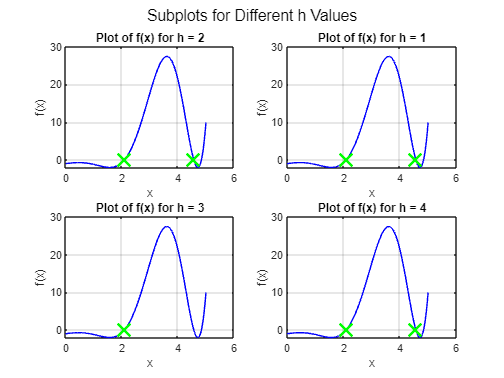

% Define the interval and different step sizes
a = 0;
b = 5;
hs = [2, 1, 3, 4];

% Initialize a cell array to store the roots for each h value
roots_all = cell(1, numel(hs));

% Initialize a cell array to store the x values for each h value
x_values_all = cell(1, numel(hs));

% Create subplots for each h value
for i = 1:numel(hs)
    h = hs(i);
    
    % Initialize an array to store the roots
    roots = [];

    % Loop through the interval with step size h
    for x = a:h:b
        % Use fzero to find a root in the current subinterval
        root = fzero(@myFunction, x);

        % Check if the root is within the current subinterval
        if root >= x && root <= x + h
            % Add the root to the array
            roots = [roots, root];
        end
    end
    
    % Store the roots and x values in cell arrays
    roots_all{i} = roots;
    x_values_all{i} = linspace(a, b, 1000);
    
    % Plot the function with a grid in the current subplot
    subplot(2, 2, i);
    y_values = myFunction(x_values_all{i});
    plot(x_values_all{i}, y_values, 'b-');
    grid on;
    xlabel('x');
    ylabel('f(x)');
    title(['Plot of f(x) for h = ', num2str(h)]);

    % Mark the roots with large green diamonds
    hold on;
    plot(roots_all{i}, myFunction(roots_all{i}), 'gx', 'MarkerSize', 15, 'MarkerFaceColor', 'g', 'LineWidth', 2);
    hold off;
end

% Adjust subplot layout
sgtitle('Subplots for Different h Values');

## **P5-5**

Write a script that solves   h(x)=x^2-x-e^-x 

## 
$$h\left(x\right)=x^2 -x-e^{-x}$$


using Fixed Point Iteration. Choose your own stopping criteria and keep track of the error at each iteration. Keep in mind that you can choose any of the following 4 formulas for your fixed point iteration: 

## 
$$g\left(x\right)=-e^{-x} +x^2$$


## 
$$g\left(x\right)=\sqrt{e^{-x} +x}$$


## 
$$g\left(x\right)=-\ln \left(x^2 -x\right)$$


## 
$$g\left(x\right)=1+\frac{e^{-x} }{x}$$


% Define the function h(x) and its derivative h'(x)
h = @(x) x.^2 - x - exp(-x);
h_prime = @(x) 2*x - 1 + exp(-x);

% Initial guess and tolerance
x0 = 1;
tolerance = 0.0001;

% Initialize variables to store results
max_iterations = 100;
error_history = zeros(max_iterations, 1);

% Formula 1: g(x) = -exp(-x) + x^2
g1 = @(x) -exp(-x) + x.^2;

% Initialize variables for Formula 1
x = x0;
iterations1 = 1;
g1list = [];

% Perform Fixed Point Iteration for Formula 1
while iterations1 < max_iterations
    g1list(end+1) = x;
    x_new = g1(x);
    error = abs(x_new - x);
    
    % Check the stopping criteria (derivative larger than 1)
    if h_prime(x) >= 1
        disp('Formula 1:');
        disp('Derivative larger than 1, stopping.');
        disp(['Number of iterations: ', num2str(iterations1)]);
        break;
    end
    
    % Check if the error is below the tolerance
    if error <= tolerance
        disp('Formula 1:');
        disp(['Number of iterations: ', num2str(iterations1)]);
        disp(['x = ', g1list]);
        break;
    end
    
    x = x_new;
    iterations1 = iterations1 + 1;
end

Formula 1:


Derivative larger than 1, stopping.


Number of iterations: 1


% Formula 2: g(x) = sqrt(exp(-x) + x)
g2 = @(x) sqrt(exp(-x) + x);

% Initialize variables for Formula 2
x = x0;
iterations2 = 1;
g2list = [];

% Perform Fixed Point Iteration for Formula 2
while iterations2 < max_iterations
    g2list(end+1) = x;
    x_new = g2(x);
    error = abs(x_new - x);
    
    % Check if the error is below the tolerance
    if error <= tolerance
        disp('Formula 2:');
        disp(['Number of iterations: ', num2str(iterations2)]);
        disp(['x = ', num2str(g2list)]);
        break;
    end
    
    x = x_new;
    iterations2 = iterations2 + 1;
end

Formula 2:


Number of iterations: 7


x = 1      1.1696      1.2166        1.23      1.2338      1.2349      1.2352


% Formula 3: g(x) = -log(x^2 - x)
g3 = @(x) -log(x.^2 - x);

% Initialize variables for Formula 3
x = x0;
iterations3 = 1;
g3list = [];

% Perform Fixed Point Iteration for Formula 3
while iterations3 < max_iterations
    g3list(end+1) = x;
    x_new = g3(x);
    error = abs(x_new - x);
    
    % Check the stopping criteria (derivative larger than 1)
    if h_prime(x) >= 1
        disp('Formula 3:');
        disp('Derivative larger than 1, stopping.');
        break;
    end
    
    % Check if the error is below the tolerance
    if error <= tolerance
        disp('Formula 3:');
        disp(['Number of iterations: ', num2str(iterations3)]);
        disp(['x = ', num2str(g3list)]);
        break;
    end
    
    x = x_new;
    iterations3 = iterations3 + 1;
end

Formula 3:


Derivative larger than 1, stopping.


% Formula 4: g(x) = 1 + exp(-x)/x
g4 = @(x) 1 + exp(-x)./x;

% Initialize variables for Formula 4
x = x0;
iterations4 = 1;
g4list = [];

% Perform Fixed Point Iteration for Formula 4
while iterations4 < max_iterations
    g4list(end+1) = x;
    x_new = g4(x);
    error = abs(x_new - x);
    
    % Check if the error is below the tolerance
    if error <= tolerance
        disp('Formula 4:');
        disp(['Number of iterations: ', num2str(iterations4)]);
        disp(['x = ', num2str(g4list)]);
        break;
    end
    
    x = x_new;
    iterations4 = iterations4 + 1;
end

Formula 4:


Number of iterations: 11


x = 1      1.3679      1.1862      1.2575      1.2261      1.2393      1.2337      1.2361       1.235      1.2355      1.2353


## **P5-6**

Write a function that takes an initial guess as input then locates a root of

## 
$$r\left(x\right)=\sin \left(x\right)\cos \left(2x\right)$$


using the Newton-Raphson Method. Remember you will have to differentiate the function to get the formula. Choose your own convergence criterion.

% Example 1: x0 = 1
[x1, n1] = newtonRaphson(1, 1e-6, 100);
fprintf('Root = %.4f (found after %d iterations)\n', x1, n1);

Root = 0.7854 (found after 4 iterations)



% Example 2: x0 = 5
[x2, n2] = newtonRaphson(5, 1e-6, 100);
fprintf('Root = %.4f (found after %d iterations)\n', x2, n2);

Root = 5.4978 (found after 5 iterations)


## **P5-7**

Use your function from question 7 to find all roots of r(x) on the interval $\left\lbrack -\pi ,\pi \right\rbrack$.

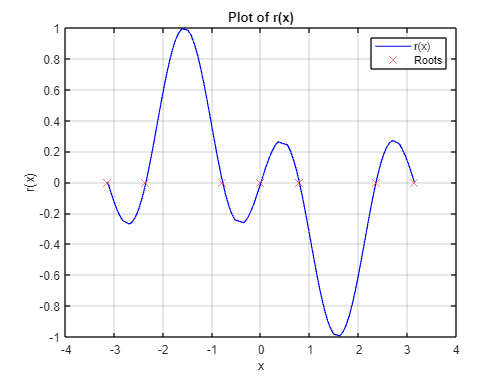

% Define the interval
interval = [-pi, pi];

% Initialize arrays to store roots and corresponding x-values
roots = [];
x_values = [];

% Define tolerance and maximum iterations
tolerance = 1e-6;
maxIterations = 100;

% Iterate through the interval and find roots
for x = linspace(interval(1), interval(2), 100)
    [root, ~] = newtonRaphson(x, tolerance, maxIterations);
    
    % Check if the root is within the specified interval
    if root >= interval(1) && root <= interval(2)
        roots = [roots, root];
        x_values = [x_values, x];
    end
end

% Define your function for plotting
r = @(x) sin(x) * cos(2 * x);

% Plot the function and roots
figure;
plot(x_values, arrayfun(r, x_values), 'b', 'LineWidth', 1);
title('Plot of r(x)');
xlabel('x');
ylabel('r(x)');

hold on;

% Plot the roots as red dots
plot(roots, arrayfun(r, roots), 'rx', 'MarkerSize', 10);
legend('r(x)', 'Roots');
grid on;
hold off;

## **P5-8**

Write a script that locates all roots of  

## 
$$w\left(x\right)=x^3 -6x^2 +10x-4$$


using the Bisection Method. Locate brackets by using the incremental search method you wrote before.

% Define the function w(x)
w = @(x) x^3 - 6*x^2 + 10*x - 4;

% Define the search interval [a, b]
a = -10; % Start with a wide interval
b = 10;
step = 0.01; % Incremental search step size

% Initialize variables
roots = []; % To store the roots
found_exact_root = false;

% Perform incremental search to locate brackets and check for exact roots
while a <= b
    if w(a) == 0
        roots = [roots, a];
        found_exact_root = true;
    elseif w(a) * w(a + step) < 0
        % Bracket found, apply Bisection method
        [root, ~] = bisection(w, a, a + step, 1e-8);
        roots = [roots, root];
    end
    
    a = a + step;
end

% Display whether an exact root was found
if found_exact_root
    disp('A root was found by the incremental search method.');
else
    disp('No exact root was found by the incremental search method.');
end

No exact root was found by the incremental search method.


% Display the roots found by the Bisection method
fprintf('The roots are:\n');

The roots are:


fprintf('root = %.4f ', roots);

root = 0.5858 root = 2.0000 root = 3.4142 

## **P5-9-1**

The volume of liquid V in a hollow horizontal cylinder of radius r and length L is related to the depth of the liquid h by, 

## 
$$v=\left\lbrack r^2 \cos^{-1} \left(\frac{r-h}{r}\right)-\left(r-h\right)\sqrt{2\textrm{rh}-h^2 }\right\rbrack L$$


Determine h given r = 2m, L = 5m, and V = 8m.

% Define a function that represents the equation
fun = @(h) (2^2 * acos((2 - h) / 2) - (2 - h) * sqrt(2 * 2 * h - h^2)) * 5 - 8;

% Use fsolve to find the value of h
h = fsolve(fun, 1); % Start with an initial guess of h = 1


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


% Display the result
fprintf('The depth of the liquid (h) is approximately %.2f meters\n', h);

The depth of the liquid (h) is approximately 0.74 meters


## **P5-9-2**

The volume of liquid V in a hollow horizontal cylinder of radius r and length L is related to the depth of the liquid h by, 

## 
$$v=\left\lbrack r^2 \cos^{-1} \left(\frac{r-h}{r}\right)-\left(r-h\right)\sqrt{2\textrm{rh}-h^2 }\right\rbrack L$$


Determine h given r = 2m, L = 5m, and V = 8m.

% Given values
r = 2;    % radius in meters
L = 5;    % length in meters
V = 8;    % volume in cubic meters

% Define the equation in terms of h
equation = @(h) (r^2 * acos((r - h) / r) - (r - h) * sqrt(2 * r * h - h^2)) * L - V;

% Use numerical solver to find h
initial_guess = 1; % Initial guess for h
h = fzero(equation, initial_guess);

% Display the result
disp('h = ');

h = 


disp(h);

    0.7400



## **P5-10**

Determine the location of the horizontal tangents (turning points) of 

## 
$$m\left(x\right)=\cos \left(\frac{x^2 }{2}\right)+\cos \left(2x\right)$$


on the interval [–π,π]. Plot the figure and mark the turning points with thick, large red circles with blue faces

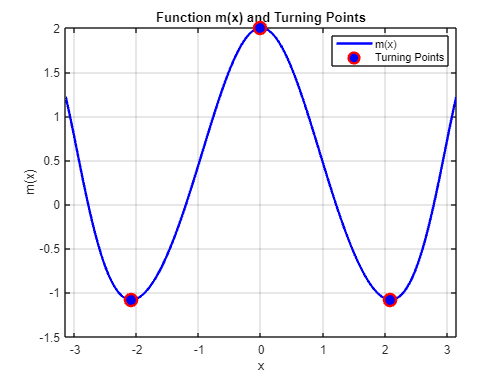

% Step 1: Create a range of x-values
x = linspace(-pi, pi, 1000);

% Define the function m(x)
m = cos(x.^2/2) + cos(2*x);

% Step 2: Calculate the derivative of m(x)
dm_dx = diff(m)./diff(x);

% Step 3: Find the x-values where the derivative is approximately zero
x_tangent = x(1:end-1) + diff(x)/2; % Use midpoints of intervals
x_turning_points = x_tangent(abs(dm_dx) < 0.01); % Tolerance can be adjusted

% Step 4: Calculate corresponding y-values
y_turning_points = cos(x_turning_points.^2/2) + cos(2*x_turning_points);

% Step 5: Plot the function and mark turning points
figure;
plot(x, m, 'b', 'LineWidth', 2);
hold on;
plot(x_turning_points, y_turning_points, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'LineWidth', 2);
title('Function m(x) and Turning Points');
xlabel('x');
ylabel('m(x)');
grid on;
xlim([-pi, pi]);

% Display legend
legend({'m(x)', 'Turning Points'}, 'Location', 'Best');

% Show the plot
hold off;

function y = myFunction(x)
    y = exp(x) .* cos(x).^2 - 2;
end

function [root, n] = bisection(func, a, b, tolerance)
    n = 0;
    while (b - a) / 2 > tolerance
        midpoint = (a + b) / 2;
        if func(midpoint) == 0
            root = midpoint;
            return;
        elseif func(a) * func(midpoint) < 0
            b = midpoint;
        else
            a = midpoint;
        end
        n = n + 1;
    end
    root = (a + b) / 2;
end

function [root, n] = newtonRaphson(x0, tolerance, maxIterations)
    % Define the function and its derivative
    r = @(x) sin(x) * cos(2 * x);
    dr = @(x) cos(x) * cos(2 * x) - 2 * sin(x) * sin(2 * x);
    
    % Initialize variables
    x = x0;
    n = 0;
    
    % Iterate using the Newton-Raphson method
    while n < maxIterations
        n = n + 1;
        xNext = x - r(x) / dr(x);
        
        % Check for convergence
        if abs(xNext - x) < tolerance
            root = xNext;
            return;
        end
        
        x = xNext;
    end
    
    % If maxIterations reached, return the current estimate
    root = x;
end